%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%DATA PRE PROCESSING (GET SIGNAL)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Fs = 25600

Fs = 25600

N = 768000 %Number of Samples 

N = 768000

f = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Healthy Machine Variables 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%NO LOAD
nlgridcurrent = noloadhealthyG.Ia(1:N);
nlgridvibration = noloadhealthyG.IMY_Radial(1:N); 
nlinvertercurrent = noloadhealthyI.Ia(1:N); 
nlinvertervibration = noloadhealthyI.IMY_Radial(1:N);

%LOADED 
gridcurrent = loadhealthyG.Ia(1:N);
gridvibration = loadhealthyG.IMY_Radial(1:N); 
invertercurrent = loadhealthyI.Ia(1:N); 
invertervibration = loadhealthyI.IMY_Radial(1:N);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Stator Winding Fault Variables 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%NO LOAD
%Grid-Fed
gridcurrent_fault1_GNL = noload2interturnG.Ia(1:N);
gridvibration_fault1_GNL = noload2interturnG.IMY_Radial(1:N);

%Inverter-Fed
invertercurrent_fault1_INL1 = noload2interturnI.Ia(1:N); 
invertervibration_fault1_INL1 = noload2interturnI.IMY_Radial(1:N);
invertercurrent_fault1_INL2 = noload4interturnI.Ia(1:N); 
invertervibration_fault1_INL2 = noload4interturnI.IMY_Radial(1:N); 

%%LOADED
%Grid-Fed
gridcurrent_fault1_GL1 = load2interturnG.Ia(1:N); 
gridvibration_fault1_GL1 = load2interturnG.IMY_Radial(1:N); 

%Inverter-Fed
invertercurrent_fault1_IL1 = load2interturnI.Ia(1:N); 
invertervibration_fault1_IL1 = load2interturnI.IMY_Radial(1:N); 
invertercurrent2_fault1_IL2= load4interturnI.Ia(1:N); 
invertervibration2_fault1_IL2 = load4interturnI.IMY_Radial(1:N); 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Broken Rotor Bar Fault Variables 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
gridcurrent_fault2_GNL = noloadbrokenG.Ia(1:N);
gridvibration_fault2_GNL = noloadbrokenG.IMY_Radial(1:N);
invertercurrent_fault2_INL = noloadbrokenI.Ia(1:N);
invertervibration_fault2_INL = noloadbrokenI.IMY_Radial(1:N);

gridcurrent_fault2_GL = loadbrokenG.Ia(1:N);
gridvibration_fault2_GL = loadbrokenG.IMY_Radial(1:N);
invertercurrent_fault2_IL = loadbrokenI.Ia(1:N);
invertervibration_fault2_IL = loadbrokenI.IMY_Radial(1:N);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% FREQUENCY-DOMAIN ANALYSIS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Current Monitoring Grid-Fed Supply Stator Winding Faults
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%
%2 shorted turns 
%%%%%%%%%%%%%%%%
%%NO LOAD
%Healthy No Load
subplot(2,1,1);
nfft = 2^nextpow2(length(nlgridcurrent));
pxx = abs(fft(nlgridcurrent,nfft)).^2/length(nlgridcurrent)/Fs;
maximum = max(pxx)

maximum = 25.0560

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.190 0.203 -140 10]);
hold on 

%No Load Fault
nfft = 2^nextpow2(length(gridcurrent_fault1_GNL));
pxx = abs(fft(gridcurrent_fault1_GNL,nfft)).^2/length(gridcurrent_fault1_GNL)/Fs;
maximum = max(pxx)

maximum = 16.2293

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.190 0.203 -140 10]);
legend('Healthy','2 shorted turns');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Grid Supply: 0% Load');
hold off

%%LOAD

%Healthy Load
subplot(2,1,2);
nfft = 2^nextpow2(length(gridcurrent));
pxx = abs(fft(gridcurrent,nfft)).^2/length(gridcurrent)/Fs;
maximum = max(pxx)

maximum = 21.4166

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.190 0.203 -140 10]);
hold on 

%Load Fault
nfft = 2^nextpow2(length(gridcurrent_fault1_GL1));
pxx = abs(fft(gridcurrent_fault1_GL1,nfft)).^2/length(gridcurrent_fault1_GL1)/Fs;
maximum = max(pxx)

maximum = 19.1268

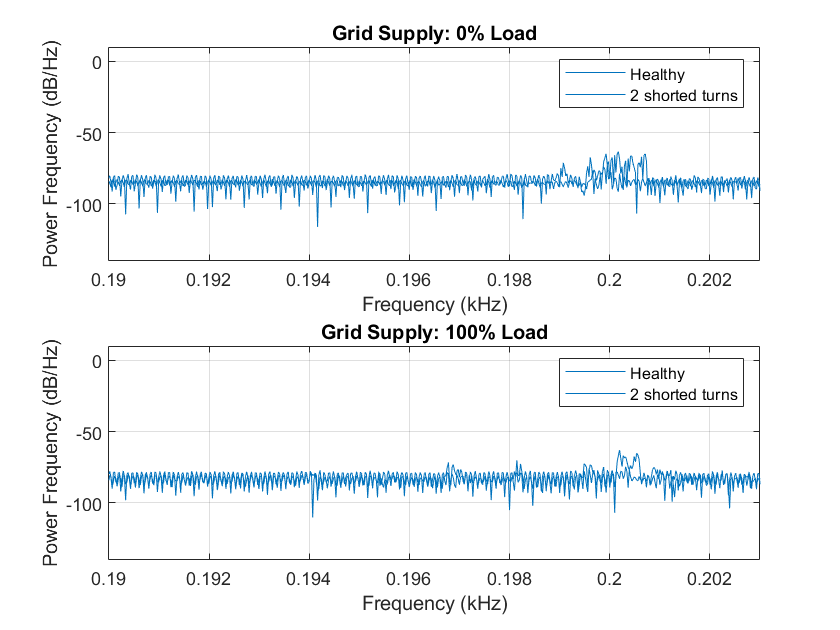

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.190 0.203 -140 10]);
legend('Healthy','2 shorted turns');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Grid Supply: 100% Load');
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Current Monitoring Inverter-Fed Supply Stator Winding Faults
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%
%2 shorted turns 
%%%%%%%%%%%%%%%%
%%No LOAD
%Healthy No Load
subplot(3,1,1);
nfft = 2^nextpow2(length(nlinvertercurrent));
pxx = abs(fft(nlinvertercurrent,nfft)).^2/length(nlinvertercurrent)/Fs;
maximum = max(pxx)

maximum = 14.6917

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
hold on 

%No Load 2 shorted Fault
nfft = 2^nextpow2(length(invertercurrent_fault1_INL1));
pxx = abs(fft(invertercurrent_fault1_INL1,nfft)).^2/length(invertercurrent_fault1_INL1)/Fs;
maximum = max(pxx)

maximum = 11.7841

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.190 0.203 -140 10]);

hold on

%No Load 4 shorted Fault
nfft = 2^nextpow2(length(invertercurrent_fault1_INL2));
pxx = abs(fft(invertercurrent_fault1_INL2,nfft)).^2/length(invertercurrent_fault1_INL2)/Fs;
maximum = max(pxx)

maximum = 11.9467

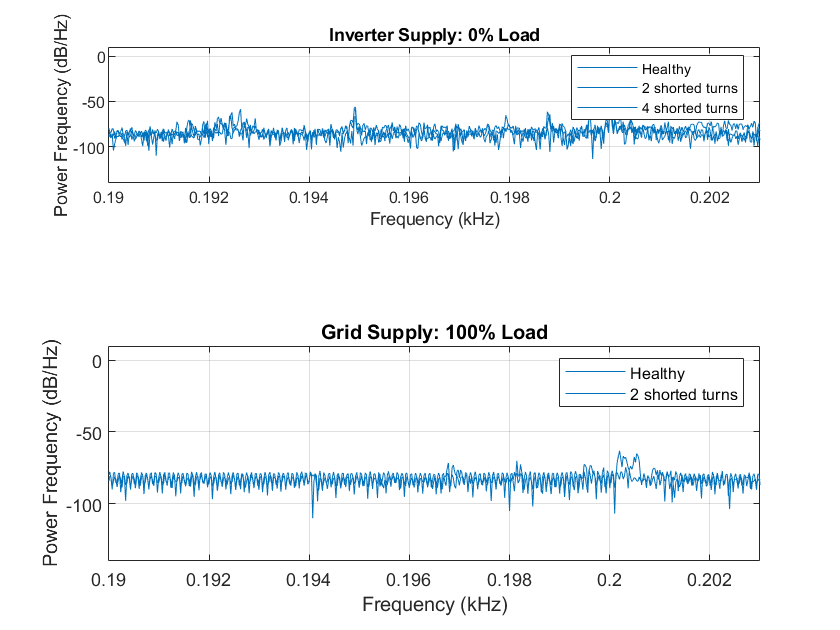

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.190 0.203 -140 10]);
legend('Healthy','2 shorted turns','4 shorted turns');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Inverter Supply: 0% Load');

hold off


%Healthy Load
subplot(3,1,2);
nfft = 2^nextpow2(length(invertercurrent));
pxx = abs(fft(invertercurrent,nfft)).^2/length(invertercurrent)/Fs;
maximum = max(pxx)

maximum = 25.5148

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
hold on 
%Load 2 shorted Fault
%subplot(3,1,2);
nfft = 2^nextpow2(length(invertercurrent_fault1_IL1));
pxx = abs(fft(invertercurrent_fault1_IL1,nfft)).^2/length(invertercurrent_fault1_IL1)/Fs;
maximum = max(pxx)

maximum = 26.6023

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.190 0.203 -140 10]);

hold on 

%Load 4 shorted Fault
%subplot(3,1,2);
nfft = 2^nextpow2(length(invertercurrent_fault1_IL1));
pxx = abs(fft(invertercurrent_fault1_IL1,nfft)).^2/length(invertercurrent_fault1_IL1)/Fs;
maximum = max(pxx)

maximum = 26.6023

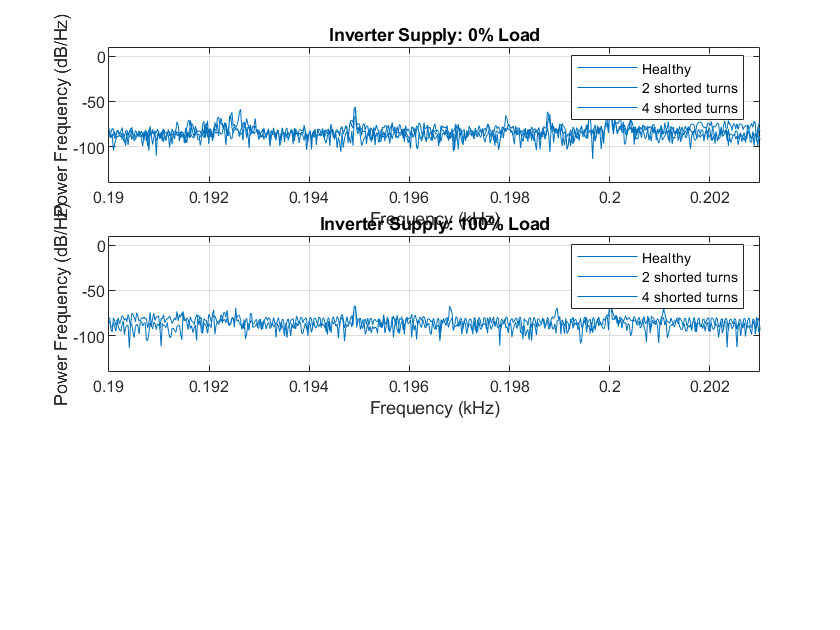

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.190 0.203 -140 10]);
legend('Healthy','2 shorted turns','4 shorted turns');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Inverter Supply: 100% Load');
hold off


  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Current Monitoring Grid-Fed Supply Broken Rotor Bar Fault 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%NO LOAD
%Healthy No Load
subplot(4,1,1);
nfft = 2^nextpow2(length(nlgridcurrent));
pxx = abs(fft(nlgridcurrent,nfft)).^2/length(nlgridcurrent)/Fs;
maximum = max(pxx)

maximum = 25.0560

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.048 0.056 -140 10]);
hold on 

%No Load Fault
nfft = 2^nextpow2(length(gridcurrent_fault2_GNL));
pxx = abs(fft(gridcurrent_fault2_GNL,nfft)).^2/length(gridcurrent_fault2_GNL)/Fs;
maximum = max(pxx)

maximum = 20.7776

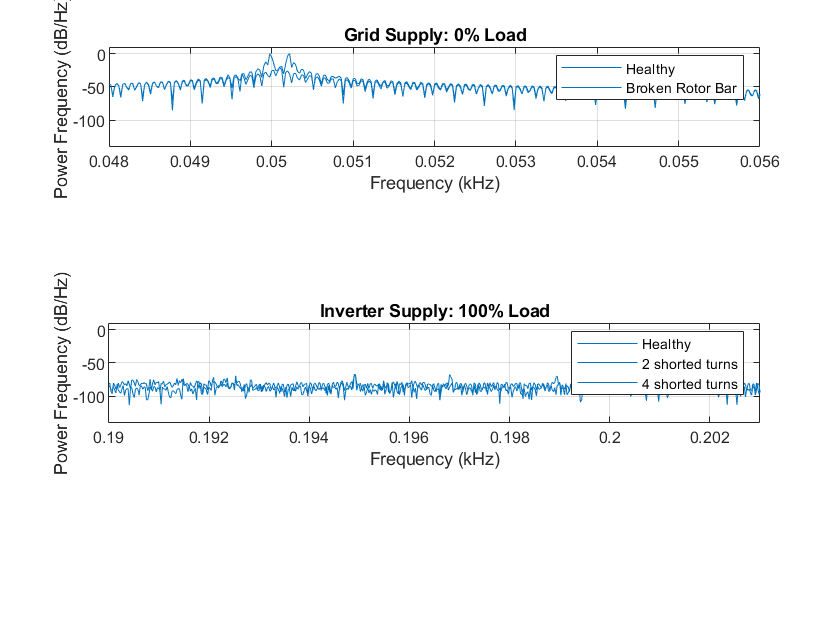

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.048 0.056 -140 10]);
legend('Healthy','Broken Rotor Bar');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Grid Supply: 0% Load');
hold off


%%LOAD

%Healthy Load
subplot(4,1,2);
nfft = 2^nextpow2(length(gridcurrent));
pxx = abs(fft(gridcurrent,nfft)).^2/length(gridcurrent)/Fs;
maximum = max(pxx)

maximum = 21.4166

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.048 0.056 -140 10]);
hold on 

%Load Fault
nfft = 2^nextpow2(length(gridcurrent_fault2_GL));
pxx = abs(fft(gridcurrent_fault2_GL,nfft)).^2/length(gridcurrent_fault2_GL)/Fs;
maximum = max(pxx)

maximum = 23.8103

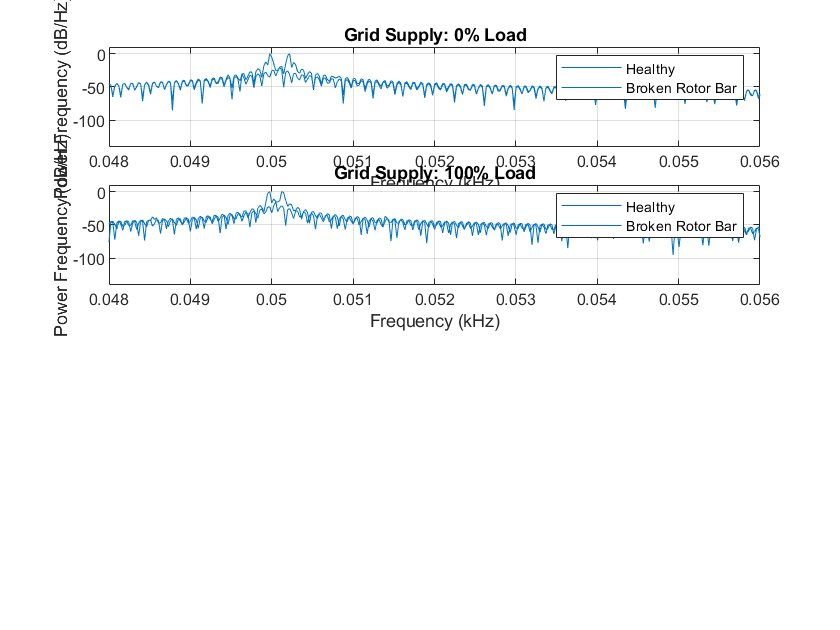

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.048 0.056 -140 10]);
legend('Healthy','Broken Rotor Bar');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Grid Supply: 100% Load');
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Current Monitoring Inverter-Fed Supply Broken Rotor Bar Faults
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%No LOAD
%Healthy No Load
subplot(5,1,1);
nfft = 2^nextpow2(length(nlinvertercurrent));
pxx = abs(fft(nlinvertercurrent,nfft)).^2/length(nlinvertercurrent)/Fs;
maximum = max(pxx)

maximum = 14.6917

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.048 0.056 -140 10]);
hold on 

%No Load Broken Rotor Bar Fault
nfft = 2^nextpow2(length(invertercurrent_fault2_INL));
pxx = abs(fft(invertercurrent_fault2_INL,nfft)).^2/length(invertercurrent_fault2_INL)/Fs;
maximum = max(pxx)

maximum = 14.5646

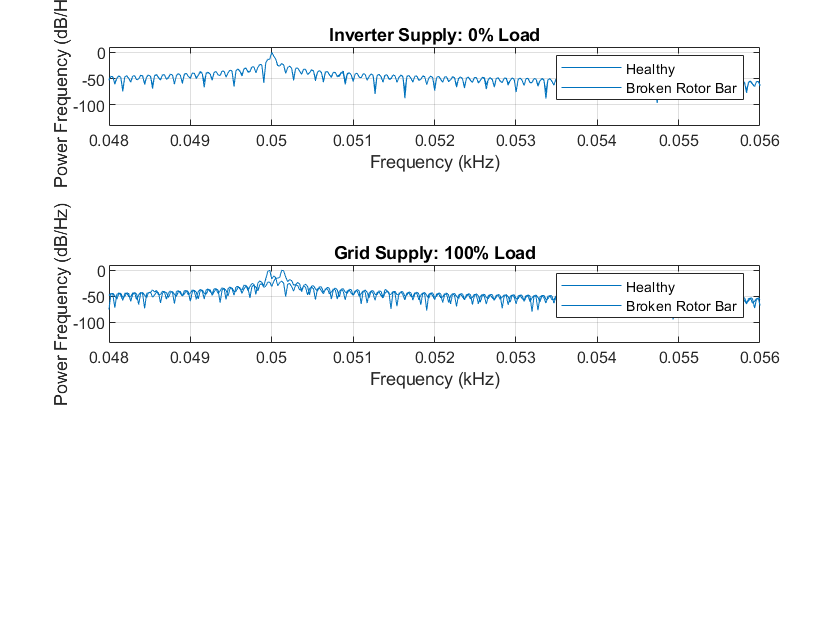

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.048 0.056 -140 10]);
legend('Healthy','Broken Rotor Bar');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Inverter Supply: 0% Load');

hold off


%LOAD

%Healthy Load
subplot(5,1,2);
nfft = 2^nextpow2(length(invertercurrent));
pxx = abs(fft(invertercurrent,nfft)).^2/length(invertercurrent)/Fs;
maximum = max(pxx)

maximum = 25.5148

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);

hold on 

%Load Broken Rotor Bar Fault
nfft = 2^nextpow2(length(invertercurrent_fault2_IL));
pxx = abs(fft(invertercurrent_fault2_IL,nfft)).^2/length(invertercurrent_fault2_IL)/Fs;
maximum = max(pxx)

maximum = 25.3777

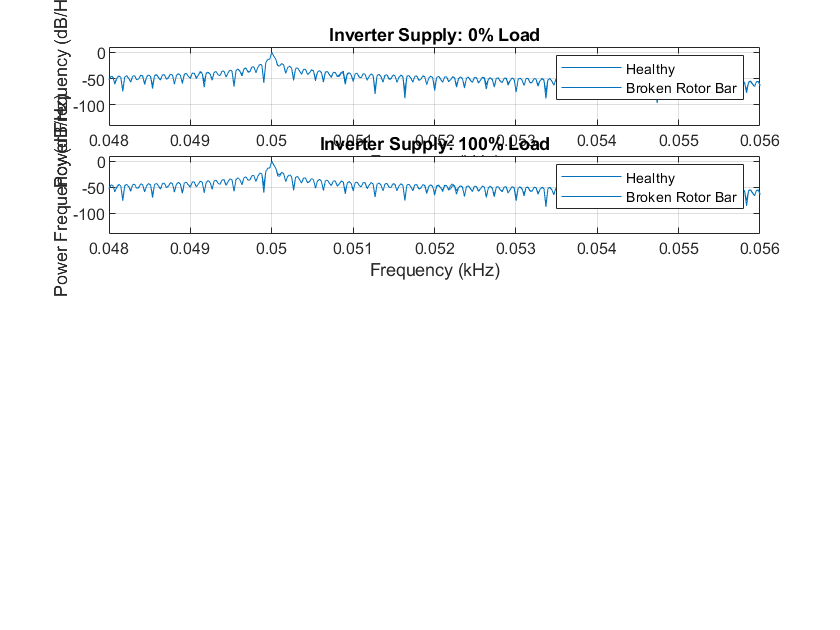

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.048 0.056 -140 10]);
legend('Healthy','Broken Rotor Bar');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Inverter Supply: 100% Load');
hold off